clear
clc

[x1,y1] = Heun_simple('funcion_simple',0,3,16,1)

y =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


x1 =          0
    0.1875
    0.3750
    0.5625
    0.7500
    0.9375
    1.1250
    1.3125
    1.5000
    1.6875


y1 =     1.0000
    1.1633
    1.2620
    1.2760
    1.2027
    1.0569
    0.8667
    0.6640
    0.4763
    0.3207


[x2,y2] = Heun_simple('funcion_simple',0,3,32,1)

y =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


x2 =          0
    0.0938
    0.1875
    0.2812
    0.3750
    0.4688
    0.5625
    0.6562
    0.7500
    0.8438


y2 =     1.0000
    1.0885
    1.1643
    1.2237
    1.2637
    1.2823
    1.2785
    1.2525
    1.2057
    1.1404


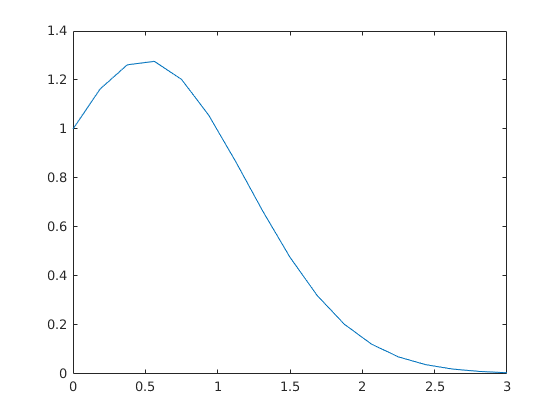

%%% graficar solucion
plot(x1,y1)

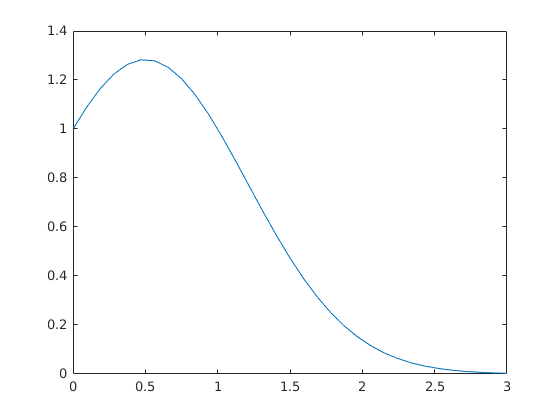

plot(x2,y2)

%%% calculo de error con N=8
solex1 = exp(1/4-(1/2-x1).^2);
error8 = abs(y1-solex1);
%plot(error8) 
%%% Valor maximo del error
error8 = max(error8)

error8 = 0.0104

%%% calculo de error con N=16
solex2 = exp(1/4-(1/2-x2).^2);
error16 = abs(y2-solex2);
%plot(error8) 
%%% Valor maximo del error
error16 = max(error16)

error16 = 0.0022

%%% orden del metodo 2^1 = 2
error8/error16

ans = 4.6193